# Digit Recognision ECE 301 Final Project Progress Report

Alex Pendergast

Heath (002)

## Data Preperation

Starting by importing the training data. T_Data which contains all the pixel values for all 42,000 images and T_Labels which contains the labels for each 28x28 image.

Train_Num = 42000; % Number of images to train with

Num_Labels = zeros([1, 10]);
for i = 1:Train_Num
    Label = Train_Labels(i,1);
    Num_Labels(1, (Label+1)) = Num_Labels(1, (Label+1)) + 1;
end
Num_Labels

Num_Labels =         4132        4684        4177        4351        4072        3795        4137        4401        4063        4188


In a fresh matrix 1x10 matrix it will count the occurences of each label and column (number + 1) for use later.

Train = zeros([1,784]);
for k = 1:10
    Train_Temp = zeros([1, 784]);
    for i = 1:Train_Num
        Label = Train_Labels(i,1);
        image = Train_Data(i,:);
        if(Label == (k-1))
            for j = 1:784
                Train_Temp(1,j) = (image(1,j)/(Num_Labels(1,k))) + Train_Temp(1,j);
            end
        end
    end
    Train = cat(3,Train,Train_Temp);   
end
Train(:,:,1) = [];

For all images with the label "k" the pixel value of each image is normalized and added to the 3D matrix T. This should generate the average value in each pixel for each number with a label.

## Training Data Set Visualization

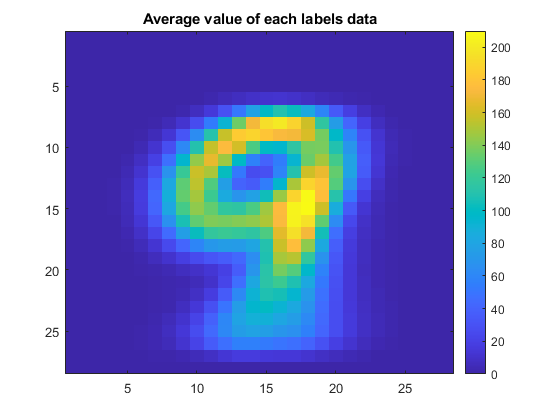

Label = 9;
Train_View = Train(:,:,Label+1);
Train_View = reshape(Train_View,[28,28])';
imagesc(Train_View);
colorbar
title("Average value of each labels data")

This code will show one slice of the 3D matrix at a time corresponding to the value selected for view. The slices are reshaped and transposed to better represent what number is being shown but no data is modified.

## Single Image Test and Visualization

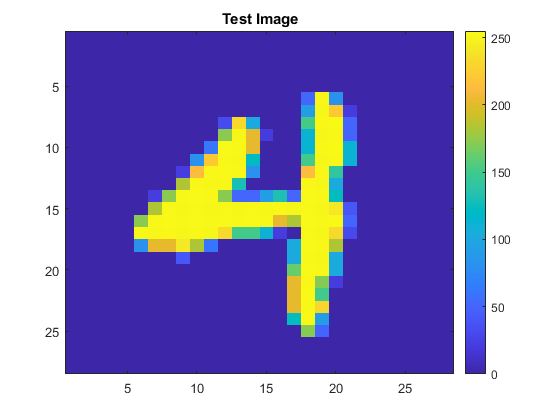

Test_Num = 24144;
Test_View = Test_Data(Test_Num,:);
Test_Case = Test_View;
Test_View = reshape(Test_View,[28,28])';
imagesc(Test_View);
title("Test Image")
colorbar

Score = zeros([1,10]);
for k = 1:10
    Train_View = Train(:,:,k);
    for i = 1:784
        if((Test_Case(1,i) - Train_View(1,i)) < 10)
            Score(1,k) = Score(1,k) + 1;
        end
    end
end
Best_Score = max(Score);
Guess = find(Score==Best_Score) - 1

Guess = 8

This allows you to look at a specific number from the testing set by changing the value of Test_Num. This also sets the image to test individually.

## Set Testing

Test_Labels = zeros([28000,1]);
for j = 1:28000
    Score = zeros([1,10]);
    Test_Case = Test_Data(j,:);
    for k = 1:10
        Train_View = Train(:,:,k);
        for i = 1:784
            if((Test_Case(1,i) - Train_View(1,i)) < 10)
                Score(1,k) = Score(1,k) + 1;
            end
        end
    end
Best_Score = max(Score);
Guess = find(Score==Best_Score) - 1;
Test_Labels(j,1) = Guess(1,1);
end

This code will run a test on all 28000 test images and generate a matrix with all of the label predictions.

## Results

Running this code in its current state will generate a submission with 36% accuracy once scored through kaggle.com. The main pitfall of this method of label assigning is its inability to differentiate between numbers located in the center of the image and the numbers eight and zero. Seen in the table below the first element and ninth element corresponding to the numbers zero and eight are heavily overrepresented in the data set. With some manual testing going one image at a time it seems that when a number aside from zero or eight are selected the prediction is correct the majority of the time. Most errors in prediction occur due to a false prediction of eight or zero. 

Test_Num = 28000;

Test_Num = 28000

Num_Test_Labels = zeros([1, 10]);
for i = 1:Test_Num
    Label = Test_Labels(i,1);
    Num_Test_Labels(1, (Label+1)) = Num_Test_Labels(1, (Label+1)) + 1;
end
Num_Test_Labels

Num_Test_Labels =        10211         668        2347        2301         644         130        1879         934        7769        1117


## Next Steps

My first plan of action to generate a higher score on image digit prediction is by focussing on any prediction with zero or eight as the final prediction. Completely removing and re-predicting any label with these numbers may lead to a higher score when testing the total data set. If only two numbers are causing problems it may be best to entirely remove them to determine the viability of the rest of the code.